harm=Dalfa(1:2)

harm = 1×2 cell array
    {[x_3    x_2    x_1]}    {[-3*x_2*x_3    -3*x_1*x_3    -3*x_1*x_2    x_1^2 + x_2^2 - 2*x_3^2    x_1^2 - 2*x_2^2 + x_3^2    - 2*x_1^2 + x_2^2 + x_3^2]}


gN1 = mapping(harm,{eye(3),[0.1 0.4 0 0 0 0;0 0.2 0 0.1 0 0;0 0 0 0.1 0.6 0]})

$$gN1 = \begin{array}{l} \left(\begin{array}{ccc} \frac{\left(r^{2}-1\right)\,\left(12\,r\,\cos\left(\theta \right)+3\,r\,\sin\left(\theta \right)-5\,r^{2}-5\right)}{\sigma_{1}} & \frac{6\,r^{3}\,\cos\left(\theta \right)+10\,r^{3}\,\sin\left(\theta \right)-6\,r\,\cos\left(\theta \right)+10\,r\,\sin\left(\theta \right)+4\,r^{2}-r^{4}-1}{\sigma_{1}} & \frac{2\,r^{4}+10\,r^{3}\,\cos\left(\theta \right)+36\,r^{2}\,{\cos\left(\theta \right)}^{2}-26\,r^{2}+10\,r\,\cos\left(\theta \right)+2}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=5\,{\left(r^{2}+1\right)}^{2} \end{array}$$

vars1=symvar(gN1)

$$vars1 = \left(\begin{array}{cc} r & \theta \end{array}\right)$$

samples=rand(2,2)*diag([1,2*pi])

samples =     0.8147    0.7979
    0.9058    5.7389


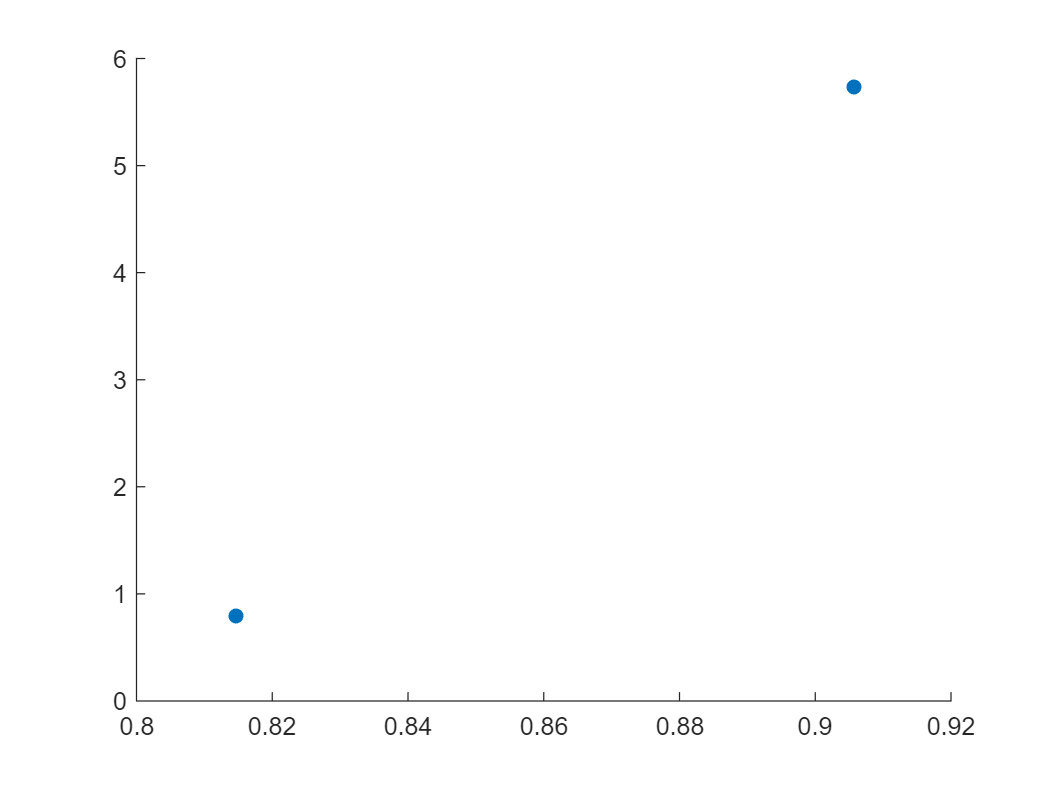

figure(2)
clf
scatter(samples(:,1),samples(:,2),'filled')

syms t
assume(t,'Real')
r = t*samples(1,1)+(1-t)*samples(2,1)

$$r = \frac{8158648460577917}{9007199254740992}-\frac{410134939838721\,t}{4503599627370496}$$

theta = t*samples(1,2)+(1-t)*samples(2,2)

$$theta = \frac{1615359490822487}{281474976710656}-\frac{22252412133826109\,t}{4503599627370496}$$

gN=subs(gN1,{vars1(1),vars1(2)},{r,theta})

$$gN = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\left({\sigma_{3}}^{2}-1\right)\,\left(12\,\cos\left(\sigma_{1}\right)\,\sigma_{3}-3\,\sin\left(\sigma_{1}\right)\,\sigma_{3}+5\,{\sigma_{3}}^{2}+5\right)}{\sigma_{2}} & \frac{6\,\cos\left(\sigma_{1}\right)\,\sigma_{3}+10\,\sin\left(\sigma_{1}\right)\,\sigma_{3}-6\,\cos\left(\sigma_{1}\right)\,{\sigma_{3}}^{3}+10\,\sin\left(\sigma_{1}\right)\,{\sigma_{3}}^{3}+4\,{\sigma_{3}}^{2}-{\sigma_{3}}^{4}-1}{\sigma_{2}} & -\frac{10\,\cos\left(\sigma_{1}\right)\,\sigma_{3}+10\,\cos\left(\sigma_{1}\right)\,{\sigma_{3}}^{3}-36\,{\cos\left(\sigma_{1}\right)}^{2}\,{\sigma_{3}}^{2}+26\,{\sigma_{3}}^{2}-2\,{\sigma_{3}}^{4}-2}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{22252412133826109\,t}{4503599627370496}-\frac{1615359490822487}{281474976710656}\\ \sigma_{2}=5\,{\left({\sigma_{3}}^{2}+1\right)}^{2}\\ \sigma_{3}=\frac{410134939838721\,t}{4503599627370496}-\frac{8158648460577917}{9007199254740992} \end{array}$$

vars2=symvar(gN)

$$vars2 = t$$

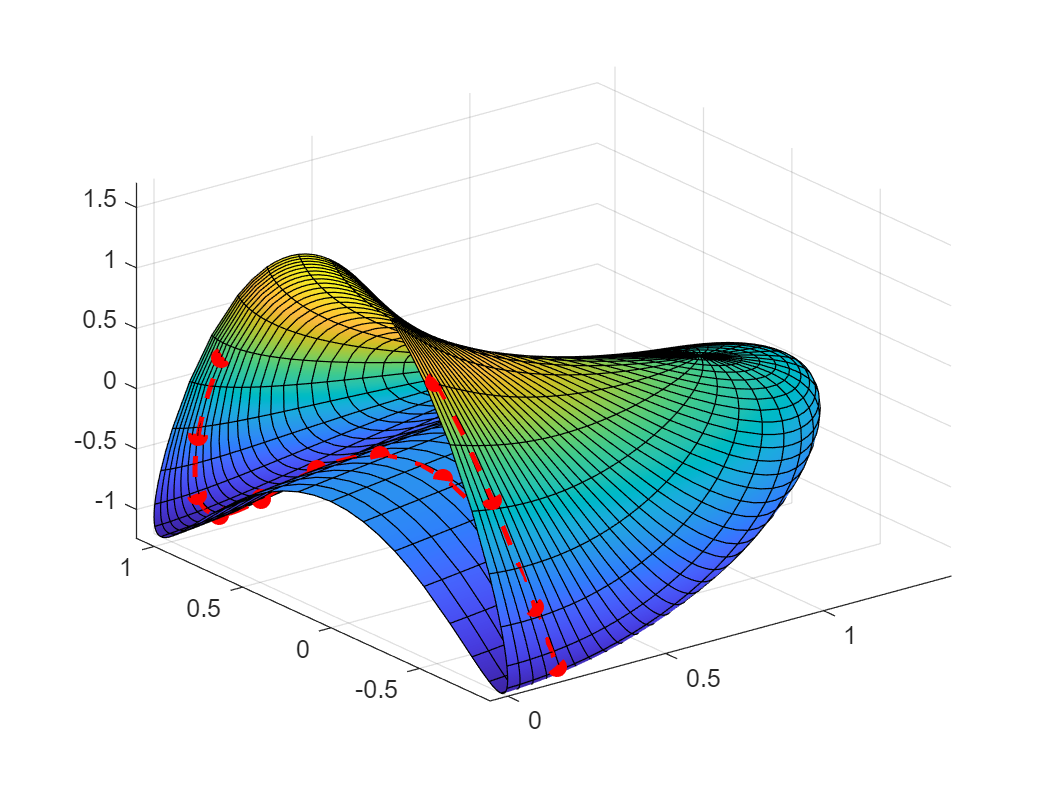

figure(3)
clf
fplot3(symfun(gN(1),vars2),symfun(gN(2),vars2),symfun(gN(3),vars2),[0 1],'--or','LineWidth',2,'MarkerFaceColor','auto')
hold on
fsurf(symfun(gN1(1),vars1),symfun(gN1(2),vars1),symfun(gN1(3),vars1),[0 1 0 2*pi])

fun=symfun(gN1,vars1)

$$fun(r, theta) = \begin{array}{l} \left(\begin{array}{ccc} \frac{\left(r^{2}-1\right)\,\left(12\,r\,\cos\left(\theta \right)+3\,r\,\sin\left(\theta \right)-5\,r^{2}-5\right)}{\sigma_{1}} & \frac{6\,r^{3}\,\cos\left(\theta \right)+10\,r^{3}\,\sin\left(\theta \right)-6\,r\,\cos\left(\theta \right)+10\,r\,\sin\left(\theta \right)+4\,r^{2}-r^{4}-1}{\sigma_{1}} & \frac{2\,r^{4}+10\,r^{3}\,\cos\left(\theta \right)+36\,r^{2}\,{\cos\left(\theta \right)}^{2}-26\,r^{2}+10\,r\,\cos\left(\theta \right)+2}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=5\,{\left(r^{2}+1\right)}^{2} \end{array}$$

Primera forma fundamental

funr=diff(gN1,vars1(1));
funtheta=diff(gN1,vars1(2));
g11=dot(funr,funr);
g12=dot(funr,funtheta);
g22=dot(funtheta,funtheta);
dr=diff(r,t);
dtheta=diff(theta,t);

fg11=subs(g11,{vars1(1),vars1(2)},{r,theta});
fg12=subs(g12,{vars1(1),vars1(2)},{r,theta});
fg22=subs(g22,{vars1(1),vars1(2)},{r,theta});

intFun=matlabFunction(symfun(sqrt(fg11*(dr)^2+2*fg12*dr*dtheta+fg22*(dtheta)^2),vars2))

intFun = function_handle with value:
    @(t)sqrt(1.0./((t.*9.106825068244029e-2-9.057919370756192e-1).^2+1.0).^4.*(cos(t.*4.941028060884391-5.738909759225262).*(t.*9.106825068244029e-2-9.057919370756192e-1).*1.0e+1-sin(t.*4.941028060884391-5.738909759225262).*(t.*9.106825068244029e-2-9.057919370756192e-1).*6.0+cos(t.*4.941028060884391-5.738909759225262).*(t.*9.106825068244029e-2-9.057919370756192e-1).^3.*1.0e+1+sin(t.*4.941028060884391-5.738909759225262).*(t.*9.106825068244029e-2-9.057919370756192e-1).^3.*6.0).^2.*9.765503319378787e-1+1.0./((t.*9.106825068244029e-2-9.057919370756192e-1).^2+1.0).^4.*(sin(t.*4.941028060884391-5.738909759225262).*(t.*9.106825068244029e-2-9.057919370756192e-1).*1.0e+1+sin(t.*4.941028060884391-5.738909759225262).*(t.*9.106825068244029e-2-9.057919370756192e-1).^3.*1.0e+1-cos(t.*4.941028060884391-5.738909759225262).*sin(t.*4.941028060884391-5.738909759225262).*(t.*9.106825068244029e-2-9.057919370756192e-1).^2.*7.2e+1).^2.*9.765503319378787e-1+((1.0./((t.*9.1

integral(intFun,0,1)

ans = 6.8757

function inds = multiind(d,n) %multiindices
    P = partitions(d,1:d,n);
    N = size(P,1);
    C = cell(1,N);
    for k = 1:N
        tmp = repelem(1:d,P(k,:));
        tmp(end+1:n) = 0;
        C{k} = unique(perms(tmp),'rows');
    end
    inds = vertcat(C{:});
end

function res = Dalfa(range)%armónicos para los valores en range
%esta es la función principal para extraer las funciones de deformación
    syms x_1 x_2 x_3
    x = [x_1,x_2,x_3];
    expre = 1/sqrt(x_1^2+x_2^2+x_3^2);
    len2 = length(range);
    res = cell(1,len2);
    
    for j=1:len2
        inds=multiind(range(j),3);
        len = size(inds,1);
        harmon=sym(zeros(1,len));
        for i=1:len
            harmon(i)=harmdiff(expre,inds(i,:),x);
        end
        res{j}=harmon;
    end
end

function expre = harmdiff(expre,inds,x)%armónico asociado a un multiíndice
    expre = diff(expre,x(1),inds(1));
    expre = diff(expre,x(2),inds(2));
    expre = diff(expre,x(3),inds(3));
    expre = -numden(expre);
end

function [hemN,hemS] = hemisferios(expr)%funciones para cada hemisferio
    syms u v r theta
    vars=symvar(expr);
    exprN = subs(expr,vars,{2*u/(u^2+v^2+1),2*v/(u^2+v^2+1),(1-u^2-v^2)/(u^2+v^2+1)});
    exprS = subs(expr,vars,{2*u/(u^2+v^2+1),2*v/(u^2+v^2+1),-(1-u^2-v^2)/(u^2+v^2+1)});
    hemN = simplify(subs(exprN,{u,v},{r*cos(theta),r*sin(theta)}));
    hemS = simplify(subs(exprS,{u,v},{r*cos(theta),r*sin(theta)}));
end

function [hemN,hemS] = mapping(harm,matrix)%creación de las 3 funciones esfera deformada
    mapp=0;
    for i=1:length(matrix)
        mapp=mapp+harm{i}*matrix{i}';
    end
    [hemN,hemS] = hemisferios(mapp);
end

function plist = partitions(total_sum,candidate_set,max_count,fixed_count)
% extracts the list of all partitions of a number as integer sums of a list of candidates
% usage: plist = partitions(total_sum,candidate_set)
% usage: plist = partitions(total_sum,candidate_set,max_count,fixed_count)
%
% PARTITIONS solves the money changing problem. E.g.,
% how can you make change for one dollar given coins
% of a given set of denominations. A good reference on
% the general problem is found here:
%
% http://en.wikipedia.org/wiki/Integer_partition
%
% PARTITIONS uses a recursive strategy to enumerate all
% possible partitions of the total_sum. This may be
% highly intensive for large sums or large sets of
% candidates.
%
% arguments: (input)
%  total_sum - scalar positive integer (to be partitioned)
%
%              BEWARE! a large total_sum can easily cause
%              stack problems. For example, the number of
%              partitions of 40 is 37338, a set that took 24
%              seconds to completely enumerate on my cpu.
%
%  candidate_set - (OPTIONAL) vector of (distinct) candidate
%              positive integers for the partitions.
%
%              Efficiency considerations force me to require
%              that the candidates be sorted in non-decreasing
%              order. An error is produced otherwise.
%
%              DEFAULT: candidate_set = 1:total_sum
%
%              BEWARE! large candidate sets can easily cause
%              stack problems
%
%  max_count - (OPTIONAL) the maximum quantity of any
%              candidate in the final sum.
%
%              max_count must be either a vector of the
%              same length as candidate_set, or a scalar
%              that applies to all elements in that set.
%
%              DEFAULT = floor(total_sum./candidate_set)
%
%  fixed_count - (OPTIONAL) Allows you to specify a fixed
%              number of terms in the partitioned sum.
%
%              fixed_count must be a positive integer if
%              supplied.
%
%              DEFAULT = []
%
% arguments: (output)
%  plist - array of partitions of total_sum. This is a list
%              of the quantity of each element such that
%              plist*candidate_set(:) yields total_sum
%
%
% example: Write 9 as an integer combination of the set [1 2 4 7]
%
%  partitions(9,[1 2 4 7])
%
% ans =
%    9     0     0     0
%    7     1     0     0
%    5     2     0     0
%    3     3     0     0
%    1     4     0     0
%    5     0     1     0
%    3     1     1     0
%    1     2     1     0
%    1     0     2     0
%    2     0     0     1
%    0     1     0     1
%
% Thus, we can write 9 = 9*1
% or 9 = 1*1 + 4*2
% or 9 = 1*2 + 1*7
% or any of 8 distinct other ways.
%
% There are 11 such ways to write 9 in terms of these
% candidates.
%
%
% example: Change a 1 dollar bill (100 cents) as an integer
%  combination of the set [1 5 10 25 50], using no more than
%  4 of any one coin denomination. Note that no pennies will
%  be allowed by the maximum constraint.
%
%  partitions(100,[1 5 10 25 50],4)
%
% ans =
%    0     4     3     2     0
%    0     2     4     2     0
%    0     3     1     3     0
%    0     1     2     3     0
%    0     0     0     4     0
%    0     4     3     0     1
%    0     2     4     0     1
%    0     3     1     1     1
%    0     1     2     1     1
%    0     0     0     2     1
%    0     0     0     0     2
%
% example: Write 13 as an integer combination of the set [2 4 6 8 10 12]
%  (Note that no such combination exists.)
%
%  partitions(13,[2 4 6 8 10 12])
%
% ans =
%   Empty matrix: 0-by-6
%
%
% example: find all possible ways to write 100 as a sum of EXACTLY 4
%  squares of the integers 1:9.
%
%  partitions(100,(1:9).^2,[],4)
% ans =
%   0    0    0    0    4    0    0    0    0
%   1    0    0    0    2    0    1    0    0
%   2    0    0    0    0    0    2    0    0
%   0    1    0    2    0    0    0    1    0
%   1    0    2    0    0    0    0    0    1
%
%
% Author: John D'Errico
% e-mail: woodchips@rochester.rr.com
% Release: 2
% Release date: 7/15/08

% default for candidate_set
if (nargin<2) || isempty(candidate_set)
  candidate_set = 1:total_sum;
end

% how many candidates are there
n = length(candidate_set);

% error checks
if any(candidate_set<0)
  error('All members of candidate_set must be >= 0')
end
% candidates must be sorted in increasng order
if any(diff(candidate_set)<0)
  error('Efficiency requires that candidate_set be sorted')
end

% check for a max_count. do we supply a default?
if (nargin<3) || isempty(max_count)
  % how high do we need look?
  max_count = floor(total_sum./candidate_set);
elseif length(max_count)==1
  % if a scalar was provided, then turn it into a vector
  max_count = repmat(max_count,1,n);
end

% check for a fixed_count
if (nargin<4) || isempty(fixed_count)
  fixed_count = [];
elseif (fixed_count<0) || (fixed_count~=round(fixed_count))
  error('fixed_count must be a positive integer if supplied')
end

% check for degenerate cases
if isempty(fixed_count)
  if total_sum == 0
    plist = zeros(1,n);
    return
  elseif (n == 0)
    plist = [];
    return
  elseif (n == 1)
    % only one element in the set. can we form
    % total_sum from it as an integer multiple?
    p = total_sum/candidate_set;
    if (p==fix(p)) && (p<=max_count)
      plist = p;
    else
      plist = [];
    end
    return
 end
else
  % there was a fixed_count supplied
  if (total_sum == 0) && (fixed_count == 0)
    plist = zeros(1,n);
    return
  elseif (n == 0) || (fixed_count <= 0)
    plist = [];
    return
  elseif (n==1)
    % there must be a non-zero fixed_count, since
    % we did not trip the last test. since there
    % is only one candidate in the set, will it work?
    if ((fixed_count*candidate_set) == total_sum) && (fixed_count <= max_count)
      plist = fixed_count;
    else
      plist = [];
    end
    return
  end
end

% finally, we can do some work. start with the
% largest element and work backwards
m = max_count(end);
% do we need to back off on m?
c = candidate_set(end);
m = min([m,floor(total_sum/c),fixed_count]);

plist = zeros(0,n);
for i = 0:m
  temp = partitions(total_sum - i*c, ...
      candidate_set(1:(end-1)), ...
      max_count(1:(end-1)),fixed_count-i);
  plist = [plist;[temp,repmat(i,size(temp,1),1)]];  %#ok
end
end